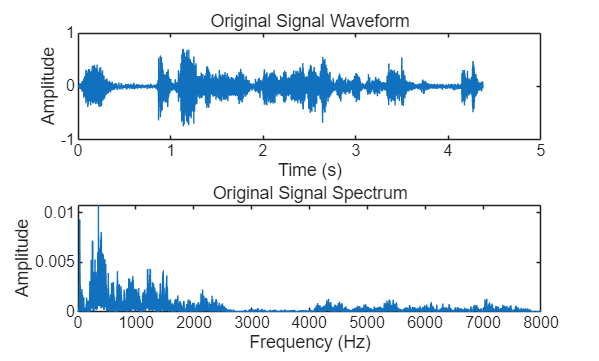

[y1, fs] = audioread("C:\Users\18237\Desktop\2.wav");
y1 = y1(:)'; 


L = length(y1);
t = (0:L-1) / fs; 
f = fs * (0:(L/2)) / L; 

LPF_cut_freq = 50;
[b0, a0] = butter(2, LPF_cut_freq/(fs/2)); 


figure('Name', 'Original Signal');
subplot(2,1,1);
plot(t, y1);
title('Original Signal Waveform');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y1_fft = fft(y1);
P1 = abs(Y1_fft/L); P1_single = P1(1:floor(L/2)+1); P1_single(2:end-1) = 2*P1_single(2:end-1);
plot(f, P1_single);
title('Original Signal Spectrum');
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

N=1

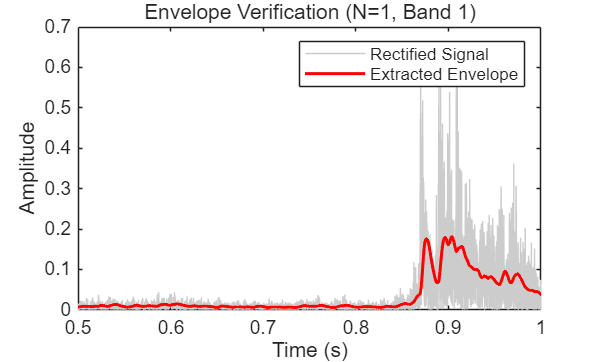

N = 1;
f_min = 200;
f_max = 7000;
d_min = log10(f_min / 165.4 + 1) / 0.06;
d_max = log10(f_max / 165.4 + 1) / 0.06;
d_edges = linspace(d_min, d_max, N + 1);
pass_band_lower = 165.4 * (10.^(0.06 * d_edges(1:end-1)) - 1);
pass_band_upper = 165.4 * (10.^(0.06 * d_edges(2:end)) - 1);
d_center = (d_edges(1:end-1) + d_edges(2:end)) / 2;
center_freq = 165.4 * (10.^(0.06 * d_center) - 1);

y1_sum = zeros(1, length(y1));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y1_band = filter(B, A, y1);
    y1_band_abs = abs(y1_band);
    y1_envelope = filter(b0, a0, y1_band_abs);
    
    if i == 1 
        figure('Name', sprintf('Envelope Verification N=%d', N));
        plot(t, y1_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y1_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (N=%d, Band 1)', N));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y1_modulated = y1_envelope .* sine_wave;
    y1_sum = y1_sum + y1_modulated;
end


e1 = sum(y1.^2);
es = sum(y1_sum.^2);
y1_1 = y1_sum * sqrt(e1 / es);

fprintf('能量验证 N=%d原始信号能量: %.4f, 归一化后信号能量: %.4f\n', N, e1, sum(y1_1.^2));

能量验证 N=1原始信号能量: 666.6279, 归一化后信号能量: 666.6279


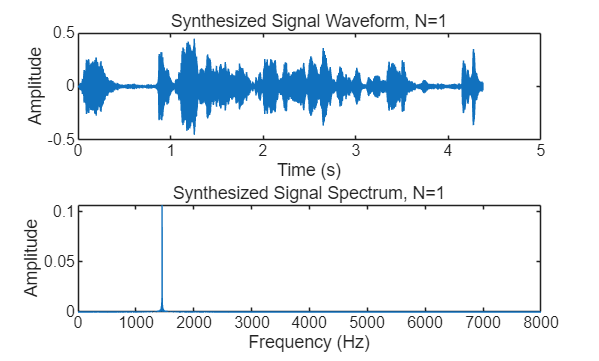


filename = sprintf('Task1_N%d.wav', N);
audiowrite(filename, y1_1, fs);

figure('Name', sprintf('Synthesized N=%d', N));
subplot(2,1,1);
plot(t, y1_1);
title(sprintf('Synthesized Signal Waveform, N=%d', N));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y1_1);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, N=%d', N));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

N=2

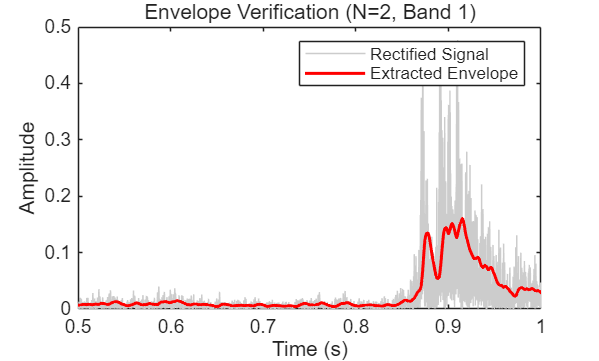

N = 2;
f_min = 200;
f_max = 7000;

d_min = log10(f_min / 165.4 + 1) / 0.06;
d_max = log10(f_max / 165.4 + 1) / 0.06;

d_edges = linspace(d_min, d_max, N + 1);

pass_band_lower = 165.4 * (10.^(0.06 * d_edges(1:end-1)) - 1);
pass_band_upper = 165.4 * (10.^(0.06 * d_edges(2:end)) - 1);

d_center = (d_edges(1:end-1) + d_edges(2:end)) / 2;
center_freq = 165.4 * (10.^(0.06 * d_center) - 1);

y1_sum = zeros(1, length(y1));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y1_band = filter(B, A, y1);
    y1_band_abs = abs(y1_band);
    y1_envelope = filter(b0, a0, y1_band_abs);
    
    if i == 1 
        figure('Name', sprintf('Envelope Verification N=%d', N));
        plot(t, y1_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y1_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (N=%d, Band 1)', N));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y1_modulated = y1_envelope .* sine_wave;
    y1_sum = y1_sum + y1_modulated;
end


e1 = sum(y1.^2);
es = sum(y1_sum.^2);
y1_2 = y1_sum * sqrt(e1 / es);

fprintf('能量验证 N=%d原始信号能量: %.4f, 归一化后信号能量: %.4f\n', N, e1, sum(y1_2.^2));

能量验证 N=2原始信号能量: 666.6279, 归一化后信号能量: 666.6279


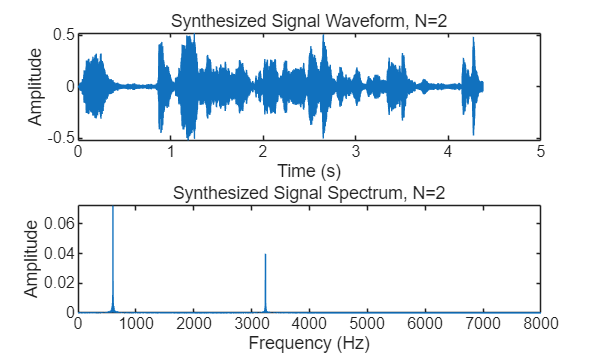


filename = sprintf('Task1_N%d.wav', N);
audiowrite(filename, y1_2, fs);

figure('Name', sprintf('Synthesized N=%d', N));
subplot(2,1,1);
plot(t, y1_2);
title(sprintf('Synthesized Signal Waveform, N=%d', N));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y1_2);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, N=%d', N));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

N=4

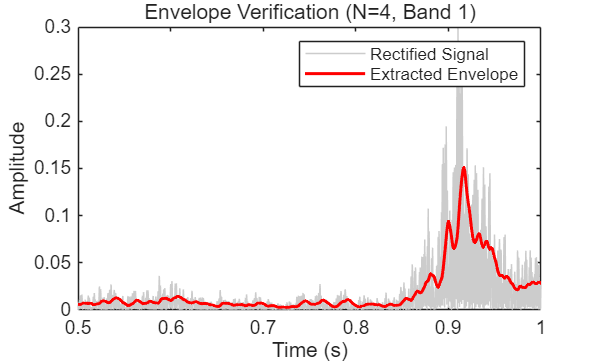

N = 4;
f_min = 200;
f_max = 7000;

d_min = log10(f_min / 165.4 + 1) / 0.06;
d_max = log10(f_max / 165.4 + 1) / 0.06;

d_edges = linspace(d_min, d_max, N + 1);

pass_band_lower = 165.4 * (10.^(0.06 * d_edges(1:end-1)) - 1);
pass_band_upper = 165.4 * (10.^(0.06 * d_edges(2:end)) - 1);

d_center = (d_edges(1:end-1) + d_edges(2:end)) / 2;
center_freq = 165.4 * (10.^(0.06 * d_center) - 1);

y1_sum = zeros(1, length(y1));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y1_band = filter(B, A, y1);
    y1_band_abs = abs(y1_band);
    y1_envelope = filter(b0, a0, y1_band_abs);
    
    if i == 1 
        figure('Name', sprintf('Envelope Verification N=%d', N));
        plot(t, y1_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y1_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (N=%d, Band 1)', N));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y1_modulated = y1_envelope .* sine_wave;
    y1_sum = y1_sum + y1_modulated;
end


e1 = sum(y1.^2);
es = sum(y1_sum.^2);
y1_4 = y1_sum * sqrt(e1 / es);

fprintf('能量验证 N=%d原始信号能量: %.4f, 归一化后信号能量: %.4f\n', N, e1, sum(y1_4.^2));

能量验证 N=4原始信号能量: 666.6279, 归一化后信号能量: 666.6279


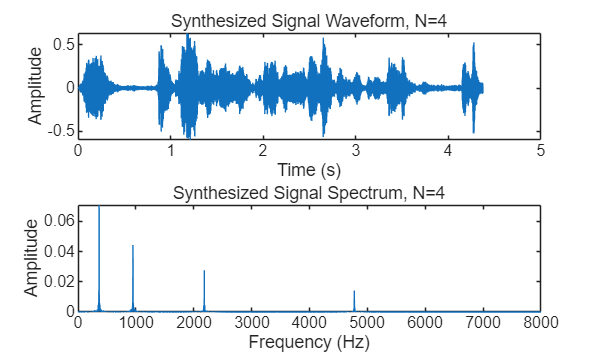


filename = sprintf('Task1_N%d.wav', N);
audiowrite(filename, y1_4, fs);

figure('Name', sprintf('Synthesized N=%d', N));
subplot(2,1,1);
plot(t, y1_4);
title(sprintf('Synthesized Signal Waveform, N=%d', N));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y1_4);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, N=%d', N));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

N=6

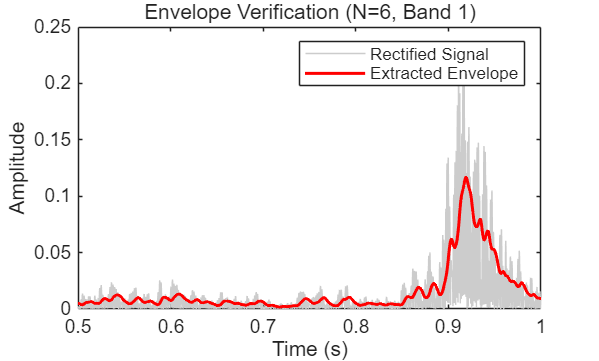

N = 6;
f_min = 200;
f_max = 7000;

d_min = log10(f_min / 165.4 + 1) / 0.06;
d_max = log10(f_max / 165.4 + 1) / 0.06;

d_edges = linspace(d_min, d_max, N + 1);

pass_band_lower = 165.4 * (10.^(0.06 * d_edges(1:end-1)) - 1);
pass_band_upper = 165.4 * (10.^(0.06 * d_edges(2:end)) - 1);

d_center = (d_edges(1:end-1) + d_edges(2:end)) / 2;
center_freq = 165.4 * (10.^(0.06 * d_center) - 1);

y1_sum = zeros(1, length(y1));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y1_band = filter(B, A, y1);
    y1_band_abs = abs(y1_band);
    y1_envelope = filter(b0, a0, y1_band_abs);
    
    if i == 1 
        figure('Name', sprintf('Envelope Verification N=%d', N));
        plot(t, y1_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y1_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (N=%d, Band 1)', N));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y1_modulated = y1_envelope .* sine_wave;
    y1_sum = y1_sum + y1_modulated;
end


e1 = sum(y1.^2);
es = sum(y1_sum.^2);
y1_6 = y1_sum * sqrt(e1 / es);

fprintf('能量验证 N=%d原始信号能量: %.4f, 归一化后信号能量: %.4f\n', N, e1, sum(y1_6.^2));

能量验证 N=6原始信号能量: 666.6279, 归一化后信号能量: 666.6279


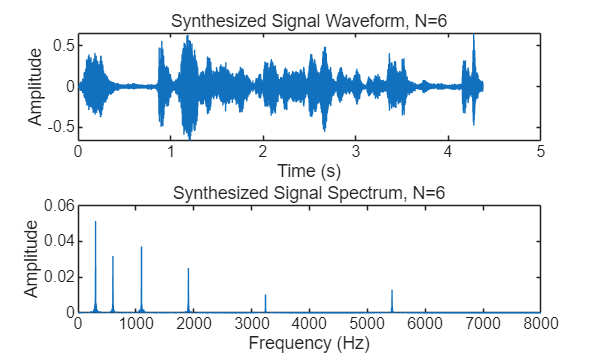


filename = sprintf('Task1_N%d.wav', N);
audiowrite(filename, y1_6, fs);

figure('Name', sprintf('Synthesized N=%d', N));
subplot(2,1,1);
plot(t, y1_6);
title(sprintf('Synthesized Signal Waveform, N=%d', N));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y1_6);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, N=%d', N));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

N=8

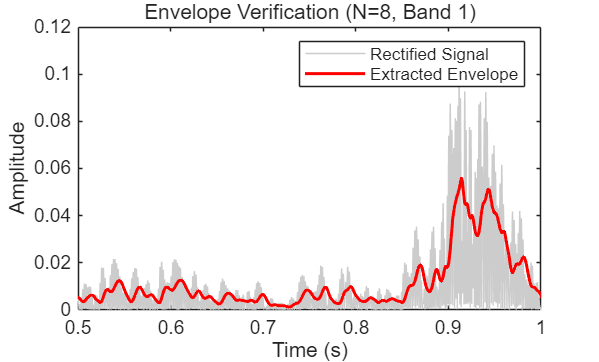


N = 8;
f_min = 200;
f_max = 7000;

d_min = log10(f_min / 165.4 + 1) / 0.06;
d_max = log10(f_max / 165.4 + 1) / 0.06;

d_edges = linspace(d_min, d_max, N + 1);

pass_band_lower = 165.4 * (10.^(0.06 * d_edges(1:end-1)) - 1);
pass_band_upper = 165.4 * (10.^(0.06 * d_edges(2:end)) - 1);

d_center = (d_edges(1:end-1) + d_edges(2:end)) / 2;
center_freq = 165.4 * (10.^(0.06 * d_center) - 1);
y1_sum = zeros(1, length(y1));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y1_band = filter(B, A, y1);
    y1_band_abs = abs(y1_band);
    y1_envelope = filter(b0, a0, y1_band_abs);
    
    if i == 1 
        figure('Name', sprintf('Envelope Verification N=%d', N));
        plot(t, y1_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y1_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (N=%d, Band 1)', N));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y1_modulated = y1_envelope .* sine_wave;
    y1_sum = y1_sum + y1_modulated;
end


e1 = sum(y1.^2);
es = sum(y1_sum.^2);
y1_8 = y1_sum * sqrt(e1 / es);

fprintf('能量验证 N=%d原始信号能量: %.4f, 归一化后信号能量: %.4f\n', N, e1, sum(y1_8.^2));

能量验证 N=8原始信号能量: 666.6279, 归一化后信号能量: 666.6279


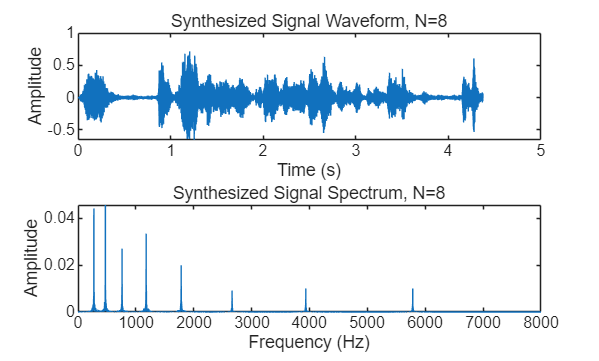


filename = sprintf('Task1_N%d.wav', N);
audiowrite(filename, y1_8, fs);

figure('Name', sprintf('Synthesized N=%d', N));
subplot(2,1,1);
plot(t, y1_8);
title(sprintf('Synthesized Signal Waveform, N=%d', N));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y1_8);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, N=%d', N));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

 N=16；

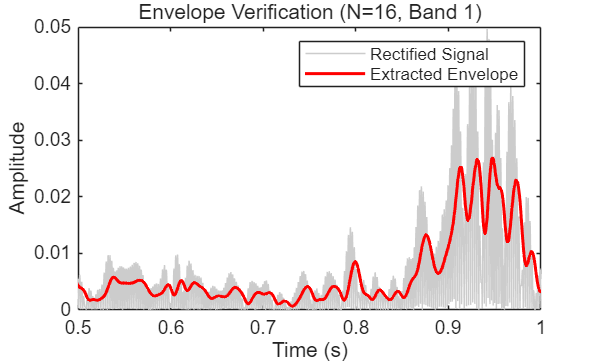

N = 16;
f_min = 200;
f_max = 7000;

d_min = log10(f_min / 165.4 + 1) / 0.06;
d_max = log10(f_max / 165.4 + 1) / 0.06;

d_edges = linspace(d_min, d_max, N + 1);

pass_band_lower = 165.4 * (10.^(0.06 * d_edges(1:end-1)) - 1);
pass_band_upper = 165.4 * (10.^(0.06 * d_edges(2:end)) - 1);

d_center = (d_edges(1:end-1) + d_edges(2:end)) / 2;
center_freq = 165.4 * (10.^(0.06 * d_center) - 1);
y1_sum = zeros(1, length(y1));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y1_band = filter(B, A, y1);
    y1_band_abs = abs(y1_band);
    y1_envelope = filter(b0, a0, y1_band_abs);
    
    if i == 1 
        figure('Name', sprintf('Envelope Verification N=%d', N));
        plot(t, y1_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y1_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (N=%d, Band 1)', N));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y1_modulated = y1_envelope .* sine_wave;
    y1_sum = y1_sum + y1_modulated;
end


e1 = sum(y1.^2);
es = sum(y1_sum.^2);
y1_8 = y1_sum * sqrt(e1 / es);

fprintf('能量验证 N=%d原始信号能量: %.4f, 归一化后信号能量: %.4f\n', N, e1, sum(y1_8.^2));

能量验证 N=16原始信号能量: 666.6279, 归一化后信号能量: 666.6279


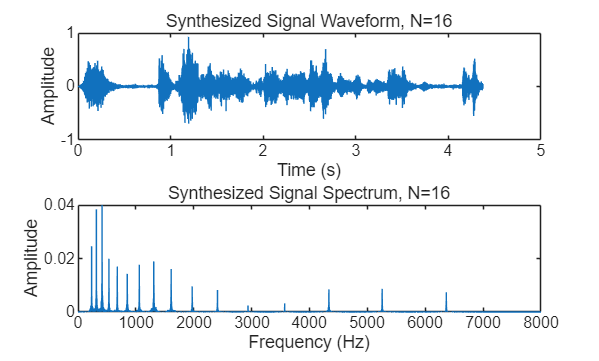


filename = sprintf('Task1_N%d.wav', N);
audiowrite(filename, y1_8, fs);

figure('Name', sprintf('Synthesized N=%d', N));
subplot(2,1,1);
plot(t, y1_8);
title(sprintf('Synthesized Signal Waveform, N=%d', N));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y1_8);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, N=%d', N));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

disp('Task 1 全部运行完毕！能量验证结果已输出在上方控制台。');

Task 1 全部运行完毕！能量验证结果已输出在上方控制台。


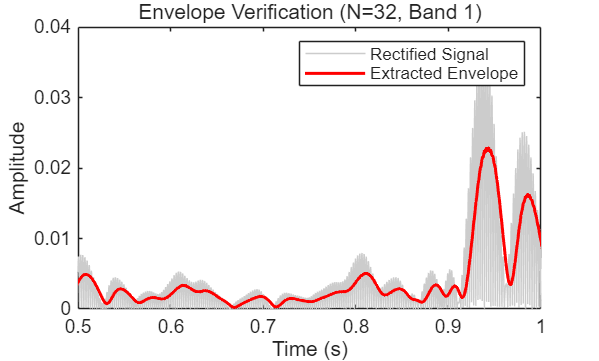

N = 32;
f_min = 200;
f_max = 7000;

d_min = log10(f_min / 165.4 + 1) / 0.06;
d_max = log10(f_max / 165.4 + 1) / 0.06;

d_edges = linspace(d_min, d_max, N + 1);

pass_band_lower = 165.4 * (10.^(0.06 * d_edges(1:end-1)) - 1);
pass_band_upper = 165.4 * (10.^(0.06 * d_edges(2:end)) - 1);

d_center = (d_edges(1:end-1) + d_edges(2:end)) / 2;
center_freq = 165.4 * (10.^(0.06 * d_center) - 1);
y1_sum = zeros(1, length(y1));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y1_band = filter(B, A, y1);
    y1_band_abs = abs(y1_band);
    y1_envelope = filter(b0, a0, y1_band_abs);
    
    if i == 1 
        figure('Name', sprintf('Envelope Verification N=%d', N));
        plot(t, y1_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y1_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (N=%d, Band 1)', N));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y1_modulated = y1_envelope .* sine_wave;
    y1_sum = y1_sum + y1_modulated;
end


e1 = sum(y1.^2);
es = sum(y1_sum.^2);
y1_8 = y1_sum * sqrt(e1 / es);

fprintf('能量验证 N=%d原始信号能量: %.4f, 归一化后信号能量: %.4f\n', N, e1, sum(y1_8.^2));

能量验证 N=32原始信号能量: 666.6279, 归一化后信号能量: 666.6279


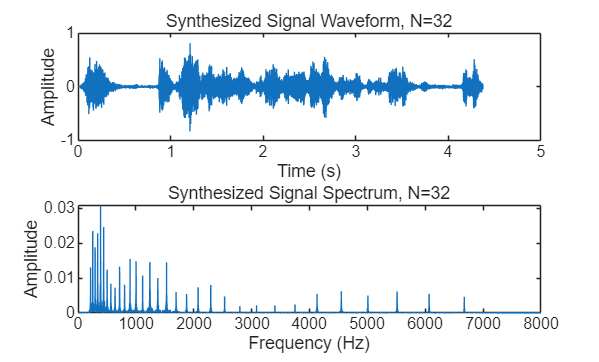


filename = sprintf('Task1_N%d.wav', N);
audiowrite(filename, y1_8, fs);

figure('Name', sprintf('Synthesized N=%d', N));
subplot(2,1,1);
plot(t, y1_8);
title(sprintf('Synthesized Signal Waveform, N=%d', N));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y1_8);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, N=%d', N));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

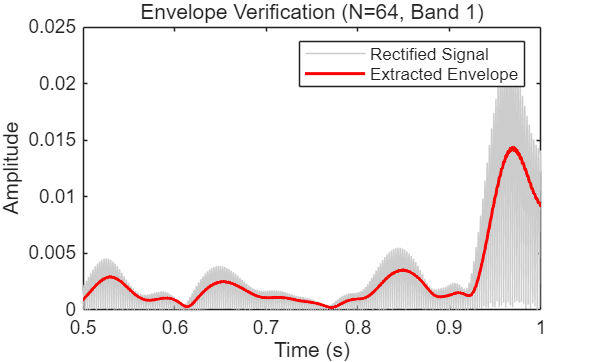

N = 64;
f_min = 200;
f_max = 7000;

d_min = log10(f_min / 165.4 + 1) / 0.06;
d_max = log10(f_max / 165.4 + 1) / 0.06;

d_edges = linspace(d_min, d_max, N + 1);

pass_band_lower = 165.4 * (10.^(0.06 * d_edges(1:end-1)) - 1);
pass_band_upper = 165.4 * (10.^(0.06 * d_edges(2:end)) - 1);

d_center = (d_edges(1:end-1) + d_edges(2:end)) / 2;
center_freq = 165.4 * (10.^(0.06 * d_center) - 1);
y1_sum = zeros(1, length(y1));
for i = 1:N
    Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);
    [B, A] = butter(4, Wn); 
    y1_band = filter(B, A, y1);
    y1_band_abs = abs(y1_band);
    y1_envelope = filter(b0, a0, y1_band_abs);
    
    if i == 1 
        figure('Name', sprintf('Envelope Verification N=%d', N));
        plot(t, y1_band_abs, 'Color', [0.8 0.8 0.8]); hold on;
        plot(t, y1_envelope, 'r', 'LineWidth', 1.5); hold off;
        title(sprintf('Envelope Verification (N=%d, Band 1)', N));
        xlabel('Time (s)'); ylabel('Amplitude');
        legend('Rectified Signal', 'Extracted Envelope');
        xlim([0.5, 1.0]); 
    end

    sine_wave = sin(2 * pi * center_freq(i) * t);
    y1_modulated = y1_envelope .* sine_wave;
    y1_sum = y1_sum + y1_modulated;
end


e1 = sum(y1.^2);
es = sum(y1_sum.^2);
y1_8 = y1_sum * sqrt(e1 / es);

fprintf('能量验证 N=%d原始信号能量: %.4f, 归一化后信号能量: %.4f\n', N, e1, sum(y1_8.^2));

能量验证 N=64原始信号能量: 666.6279, 归一化后信号能量: 666.6279


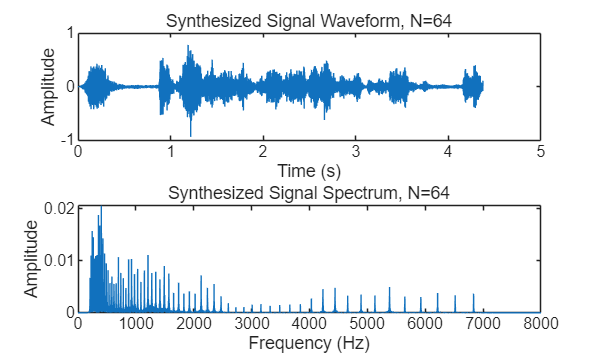


filename = sprintf('Task1_N%d.wav', N);
audiowrite(filename, y1_8, fs);

figure('Name', sprintf('Synthesized N=%d', N));
subplot(2,1,1);
plot(t, y1_8);
title(sprintf('Synthesized Signal Waveform, N=%d', N));
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
Y_fft = fft(y1_8);
P = abs(Y_fft/L); P_single = P(1:floor(L/2)+1); P_single(2:end-1) = 2*P_single(2:end-1);
plot(f, P_single);
title(sprintf('Synthesized Signal Spectrum, N=%d', N));
xlabel('Frequency (Hz)'); ylabel('Amplitude');
xlim([0, 8000]);

%% Play Task 1 synthesized results

file_list = {
    %"C:\Users\18237\Desktop\2.wav"
    %'Task1_N1.wav'
    %'Task1_N2.wav'
    'Task1_N4.wav'
    %'Task1_N6.wav'
    %'Task1_N8.wav'
    'Task1_N16.wav'
    'Task1_N32.wav'
    'Task1_N64.wav'
    
};

for k = 1:length(file_list)
    [y_play, fs_play] = audioread(file_list{k});

    if size(y_play, 2) > 1
        y_play = mean(y_play, 2);
    end

    y_play = y_play / max(abs(y_play));

    fprintf('Now playing: %s\n', file_list{k});
    player = audioplayer(y_play, fs_play);
    playblocking(player);

    pause(1);
end

Now playing: Task1_N4.wav
Now playing: Task1_N16.wav
Now playing: Task1_N32.wav
Now playing: Task1_N64.wav
